# **Valores de entrada pára el método de Runge Kutta de segundo orden**

**Nombre**: Armando Arredondo Valle

**Fecha**: 24/05/2022

clc;
clear all;

**Datos de entrada:**

x0 = input("Ingrese el valor inicial de x: ");
y0 = input("Ingrese el valor inicial de y: ");
xf = input("Ingrese el valor final de x: ");
h = input("Ingrese el valor de h: ");

**Definir los vectores de X y Y**

N = (xf-x0)/h+1;
x = zeros(N,1);
y = zeros(N,1);

**Ingresar la función en la ecuación diferencial:**

fu = input('Ingrese la ecuación diferencial:, f''(x,y) = ','s');
S = vectorize(char(fu));
fun = str2func(['@(x,y)',fu]);
a2 = input('Ingrese el valor de a2, Heun 1/2, Ralston 2/3, o Punto Medio 1: ')

a2 = 0.5000

**Función**

 
       it         x_i     y_i
      ______________________________
	0	1.00000	4.00000
	1	1.20000	4.45171
	2	1.40000	5.01664
	3	1.60000	5.71031


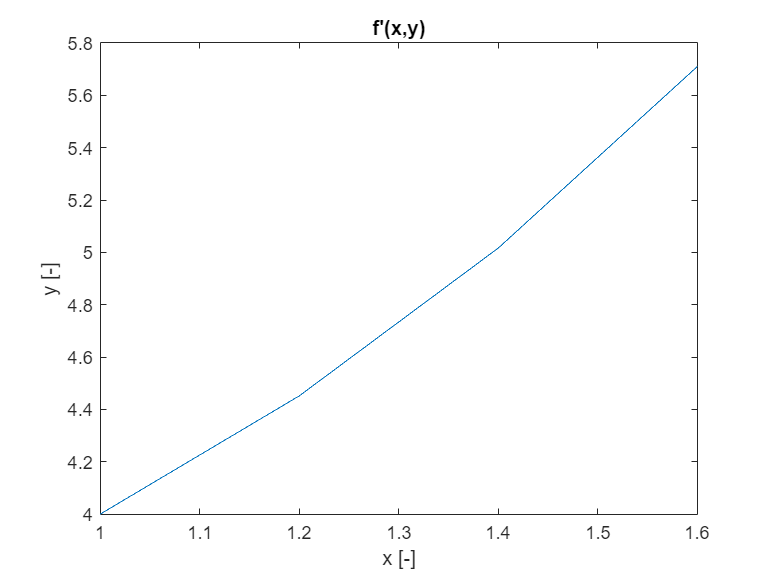

RungeKuttaFunction(x0,y0,xf,h,x,y,fun,a2);